## Estimate model from square wave, validate with sine wave

load tower_crane_square_test_data.mat
t=data_crane(1,:)';
y_arm=data_crane(2,:)';
y_pendulum=data_crane(3,:)';
u=data_crane(4,:)';
  
Ts=0.002;
N=length(t);
t=(0:Ts:(N-1)*Ts)';

First for the crane arm

y = y_pendulum

y =          0
         0
         0
         0
         0
         0
         0
         0
         0
    0.0031


data = iddata(y, u, Ts)

data =

Time domain data set with 5001 samples.
Sample time: 0.002 seconds              
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        


Gest = tfest(data, 2, 0, 0)

Gest =
 
  From input "u1" to output "y1":
         -33.86
  --------------------
  s^2 + 0.7251 s + 230
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 72.2%                    
FPE: 0.002722, MSE: 0.002717                     


See fit on training data

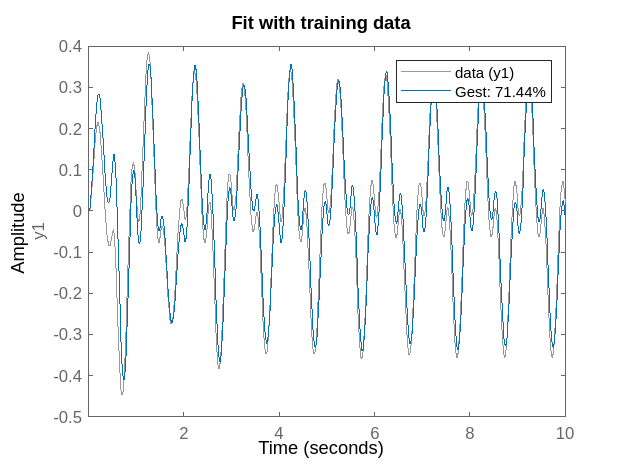

myCompare(data, Gest)
title('Fit with training data')

See fit on validation data

function myCompare(data, Gest)
    opt = compareOptions;
    opt.InitialCondition = 'z';
    compare(data, Gest, opt);  
end